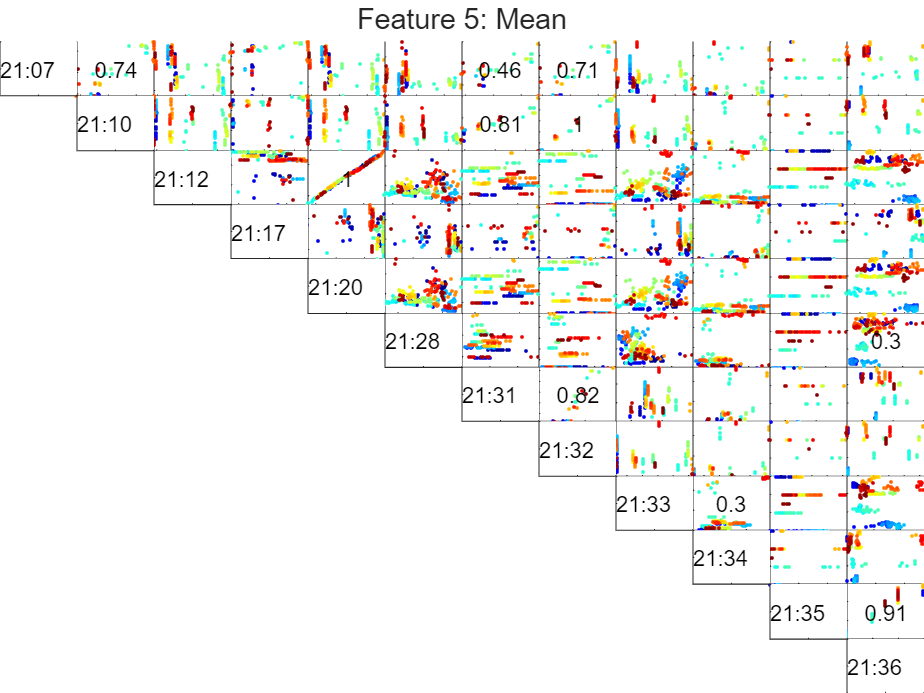

% As an example take feature 5, the Mean, of each signal.
% Plot the mean of each signal against each of the others.
% Compute the R2 value and if it's above 0.3 print the value.
R2 = plotSignalVsSignal(5, FeaturesAll, featureNames, signalName, sensorNames);

% Print the table of R2 values verse every other signal
% Lower diagonal all 0 because it would just be a mirror image of the top
% triangle
disp(num2str(R2, '%.2f  '));

0.00  0.74  0.29  0.17  0.29  0.01  0.46  0.71  0.03  0.00  0.00  0.00
0.00  0.00  0.18  0.14  0.18  0.00  0.81  1.00  0.00  0.04  0.00  0.01
0.00  0.00  0.00  0.10  1.00  0.04  0.02  0.17  0.15  0.00  0.17  0.12
0.00  0.00  0.00  0.00  0.09  0.12  0.09  0.14  0.01  0.00  0.00  0.00
0.00  0.00  0.00  0.00  0.00  0.05  0.02  0.17  0.15  0.00  0.16  0.12
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.05  0.29  0.30
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.82  0.03  0.10  0.02  0.00
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.05  0.00  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.30  0.12  0.06
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.01
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.91
0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00  0.00


% As an example, take the first row
% Signal 1 has an R2 value greater than 0.3 with Signal 2, 7 and 8
% Thus these four signals could form a good mode.
fs = 5; % Sampling frequency 
signalArray = [1, 2, 7, 8]; % Array of correlated signals for models
sig1 = FeaturesAll.(signalName(signalArray(1)) + featureNames(5));
sig2 = FeaturesAll.(signalName(signalArray(2)) + featureNames(5));
sig3 = FeaturesAll.(signalName(signalArray(3)) + featureNames(5));
sig4 = FeaturesAll.(signalName(signalArray(4)) + featureNames(5));

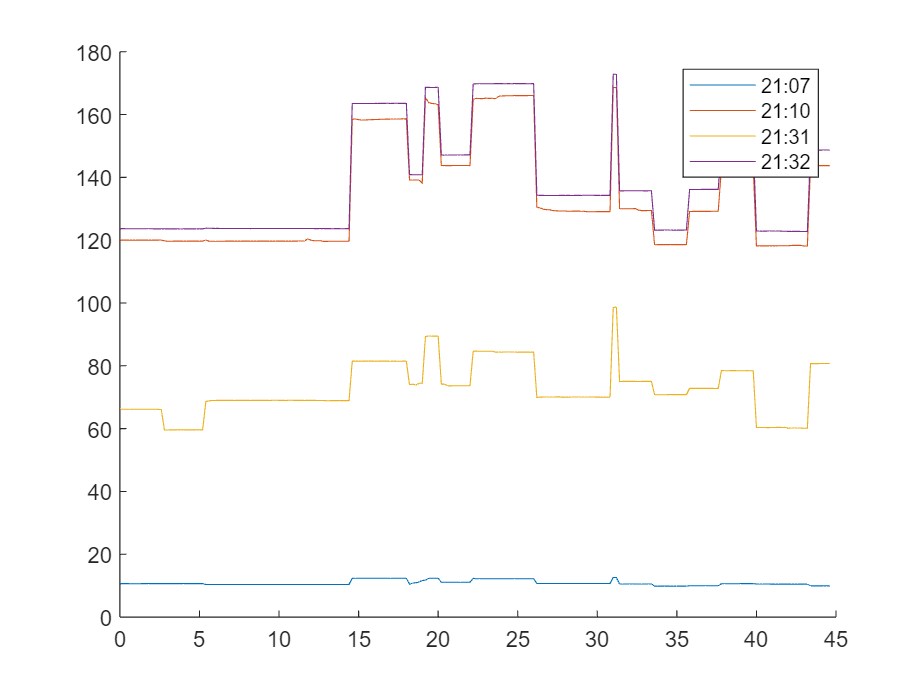

% Plot the identified signals for the Mean of each signal
n = size(sig1, 1); % Sample Size
t = ( 0 : 1/fs : (n / fs) - 1/fs)';
figure(); hold on;
plot(t, sig1);
plot(t, sig2);
plot(t, sig3);
plot(t, sig4);
txt1 = char(sensorNames(signalArray(1)));
txt2 = char(sensorNames(signalArray(2)));
txt3 = char(sensorNames(signalArray(3)));
txt4 = char(sensorNames(signalArray(4)));
leg = legend(txt1(1:5), txt2(1:5), txt3(1:5), txt4(1:5));

% Since there are four signals, let's try some models with three signals
% Keep Signal 3 as output to begin and try 3 candidates with combinations of the
% remaining signals
k = 3; % Number of parameters

% Model candidate 1
% Use Signal 4 as output, 1 and 2 as input
X1 = sig1;
X2 = sig2;
X3 = sig4;

X = [ones(size(X1)) X1 X2];
Y = X3;

beta = lsqr(X, Y);

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.0075.


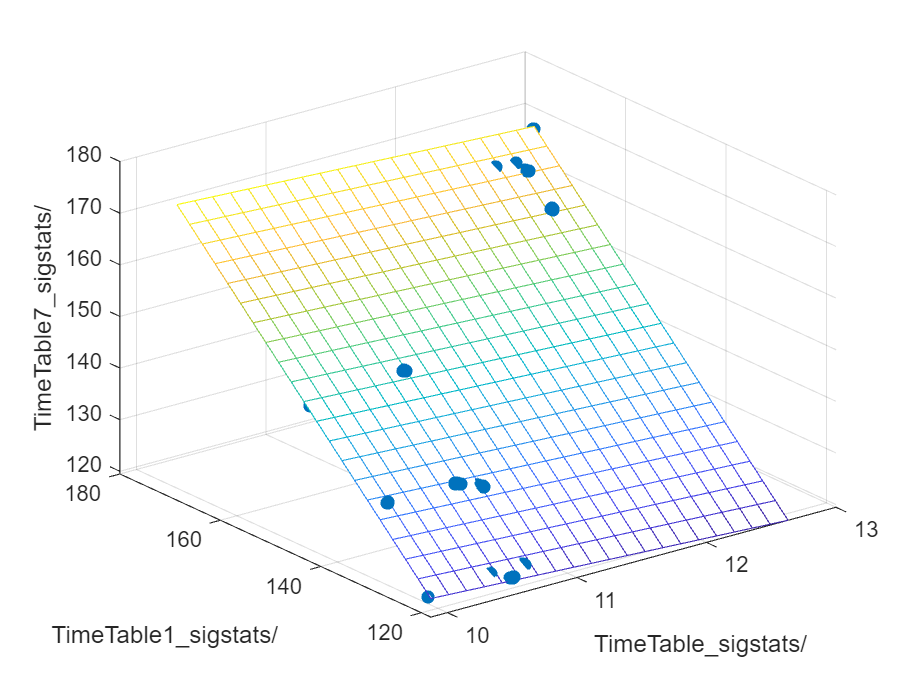

Y_est = X * beta;
%RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

% From Matlab AIC function
%    'nAIC': Normalized Akaike's Information Criterion (default)
%            nAIC = log(det(E'*E/N)) + 2d/N
%     'AIC': Akaike's Information Criterion (raw measure)
%            AIC = N*nAIC + N*(ny*log(2*pi) + 1)

AIC(1) = -2*(log(RSS)) + 2*k;
AIC2(1) = 2 * k + n * log (RSS / n); % Which is the better equation?

% An alternative formula for least squares regression type analyses 
% for normally distributed errors:
% https://www.statisticshowto.com/akaikes-information-criterion/
deltaAIC(1) = 2 * k + n * log(RSS);

figure();
title("Model Candidate 1");
scatter3(X1,X2,Y,'filled');
hold on;
interval1 = (max(X1) - min(X1))/20;
x1fit = min(X1):interval1:max(X1);
interval2 = (max(X2) - min(X2))/20;
x2fit = min(X2):interval2:max(X2);
[X1FIT,X2FIT] = meshgrid(x1fit, x2fit);
%YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT + b(4)*X1FIT.*X2FIT;
YFIT = beta(1) + beta(2).*X1FIT + beta(3).*X2FIT;
mesh(X1FIT, X2FIT, YFIT);
xlabel(signalName(signalArray(1)), 'Interpreter', 'none');
ylabel(signalName(signalArray(2)), 'Interpreter', 'none');
zlabel(signalName(signalArray(4)), 'Interpreter', 'none');

%view(50,10);

% Model candidate 2
% Use Signal 4 as output, 1 and 3 as input
X1 = sig1;
X2 = sig3;
X3 = sig4;

X = [ones(size(X1)) X1 X2];
Y = X3;

beta = lsqr(X, Y);

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.034.


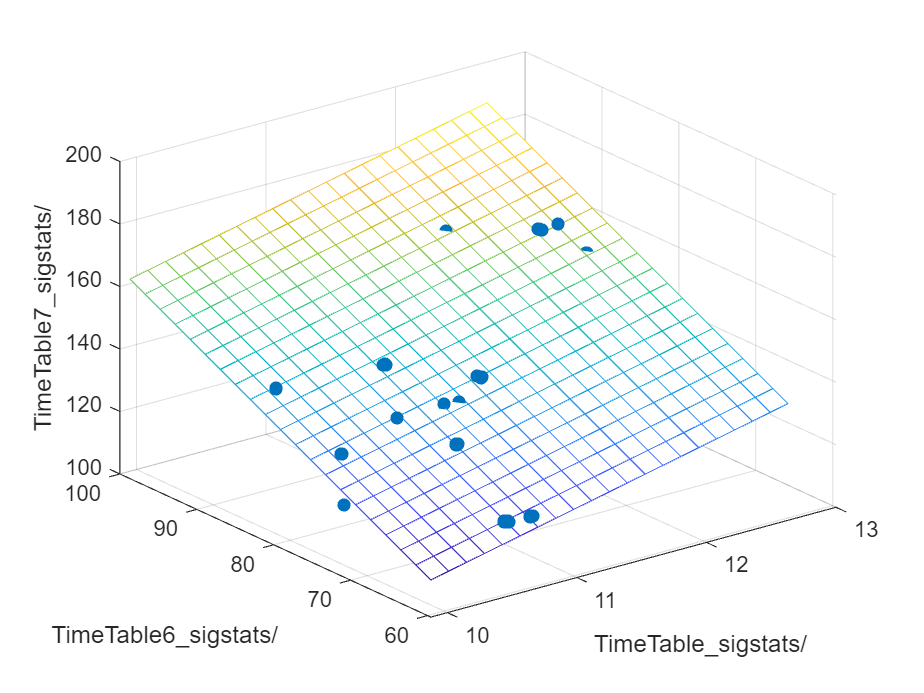

Y_est = X * beta;
%RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

deltaAIC(2) = 2 * k + n * log(RSS);
AIC(2) = -2*(log(RSS)) + 2*k;
AIC2(2) = 2 * k + n * log (RSS / n);

figure();
title("Model Candidate 2");
scatter3(X1,X2,Y,'filled');
hold on;
interval1 = (max(X1) - min(X1))/20;
x1fit = min(X1):interval1:max(X1);
interval2 = (max(X2) - min(X2))/20;
x2fit = min(X2):interval2:max(X2);
[X1FIT,X2FIT] = meshgrid(x1fit, x2fit);
%YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT + b(4)*X1FIT.*X2FIT;
YFIT = beta(1) + beta(2).*X1FIT + beta(3).*X2FIT;
mesh(X1FIT, X2FIT, YFIT);
xlabel(signalName(signalArray(1)), 'Interpreter', 'none');
ylabel(signalName(signalArray(3)), 'Interpreter', 'none');
zlabel(signalName(signalArray(4)), 'Interpreter', 'none');

%view(50,10);

% Model candidate 3
% Use Signal 4 as output, 2 and 3 as input
X1 = sig2;
X2 = sig3;
X3 = sig4;

X = [ones(size(X1)) X1 X2];
Y = X3;

beta = lsqr(X, Y);

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.008.


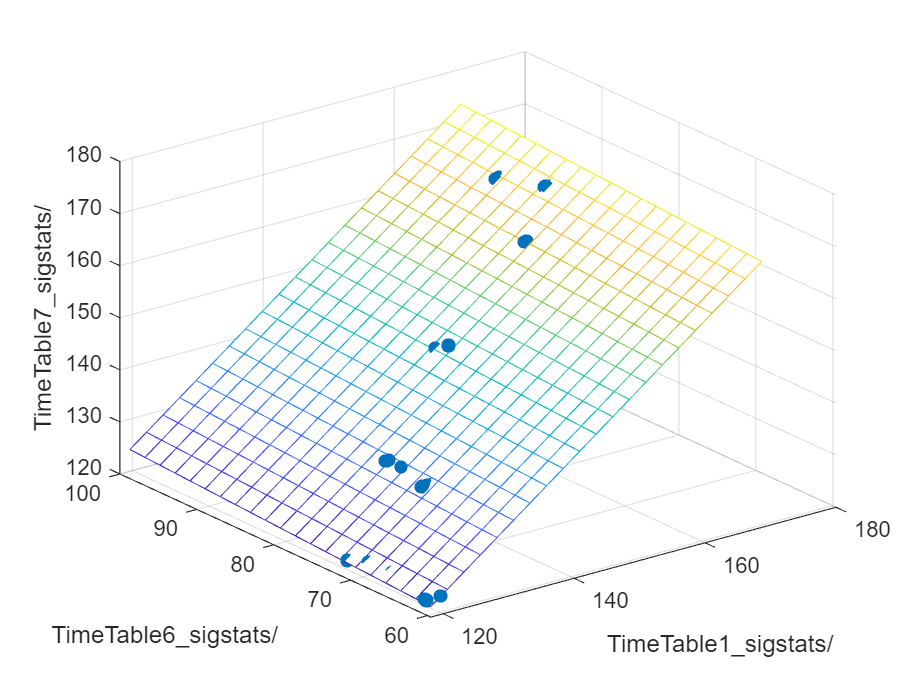

Y_est = X * beta;
%RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

deltaAIC(3) = 2 * k + n * log(RSS);
AIC(3) = -2*(log(RSS)) + 2*k;
AIC2(3) = 2 * k + n * log (RSS / n);

figure();
title("Model Candidate 3");
scatter3(X1,X2,Y,'filled');
hold on;
interval1 = (max(X1) - min(X1))/20;
x1fit = min(X1):interval1:max(X1);
interval2 = (max(X2) - min(X2))/20;
x2fit = min(X2):interval2:max(X2);
[X1FIT,X2FIT] = meshgrid(x1fit, x2fit);
%YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT + b(4)*X1FIT.*X2FIT;
YFIT = beta(1) + beta(2).*X1FIT + beta(3).*X2FIT;
mesh(X1FIT, X2FIT, YFIT);
xlabel(signalName(signalArray(2)), 'Interpreter', 'none');
ylabel(signalName(signalArray(3)), 'Interpreter', 'none');
zlabel(signalName(signalArray(4)), 'Interpreter', 'none');

%view(50,10);

% Model candidate 4
% Use Signal 3 as output, 1 and 2 as input
X1 = sig1;
X2 = sig2;
X3 = sig3;

X = [ones(size(X1)) X1 X2];
Y = X3;

beta = lsqr(X, Y);

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.041.


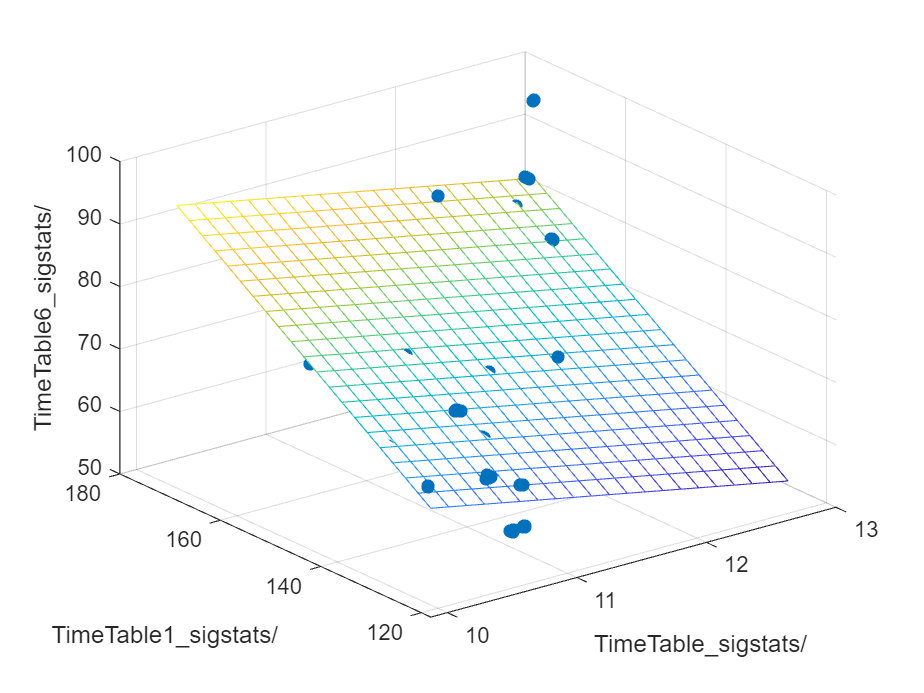

Y_est = X * beta;
%RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

deltaAIC(4) = 2 * k + n * log(RSS);
AIC(4) = -2*(log(RSS)) + 2*k;
AIC2(4) = 2 * k + n * log (RSS / n);

figure();
title("Model Candidate 4");
scatter3(X1,X2,Y,'filled');
hold on;
interval1 = (max(X1) - min(X1))/20;
x1fit = min(X1):interval1:max(X1);
interval2 = (max(X2) - min(X2))/20;
x2fit = min(X2):interval2:max(X2);
[X1FIT,X2FIT] = meshgrid(x1fit, x2fit);
%YFIT = b(1) + b(2)*X1FIT + b(3)*X2FIT + b(4)*X1FIT.*X2FIT;
YFIT = beta(1) + beta(2).*X1FIT + beta(3).*X2FIT;
mesh(X1FIT, X2FIT, YFIT);
xlabel(signalName(signalArray(1)), 'Interpreter', 'none');
ylabel(signalName(signalArray(2)), 'Interpreter', 'none');
zlabel(signalName(signalArray(3)), 'Interpreter', 'none');

%view(50,10);

% Model candidate 5
% For comparison also compute a mode with all four of the parameters
k = 4;
X1 = sig1;
X2 = sig2;
X3 = sig3;
X4 = sig4;

X = [ones(size(X1)) X1 X2 X3];
Y = X4;

beta = lsqr(X, Y);

lsqr stopped at iteration 4 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 4) has relative residual 0.0082.


Y_est = X * beta;
%RSS = sum((Y_est - Y).^2);
RSS = var(Y_est - Y) / var(Y);

deltaAIC(5) = 2 * k + n * log(RSS);
AIC(5) = -2*(log(RSS)) + 2*k;
AIC2(5) = 2 * k + n * log (RSS / n);

format short;
disp(single(deltaAIC));

   1.0e+03 *

   -1.2455   -0.5670   -1.2127   -0.4258   -1.2032



disp(AIC);

   17.1737   11.1164   16.8812    9.8552   18.8143



disp(AIC2);

   1.0e+03 *

   -2.4577   -1.7793   -2.4249   -1.6380   -2.4154




for i=1:size(AIC, 2)
    fprintf("Model Candidate %i: delta AIC = %.1f, AIC = %.2f, AIC2 = %.2f\n", i, deltaAIC(i), AIC(i), AIC2(i));
end

Model Candidate 1: delta AIC = -1245.5, AIC = 17.17, AIC2 = -2457.66
Model Candidate 2: delta AIC = -567.0, AIC = 11.12, AIC2 = -1779.25
Model Candidate 3: delta AIC = -1212.7, AIC = 16.88, AIC2 = -2424.90
Model Candidate 4: delta AIC = -425.8, AIC = 9.86, AIC2 = -1637.99
Model Candidate 5: delta AIC = -1203.2, AIC = 18.81, AIC2 = -2415.41


% Note: For AIC a small value indicates a model with a low test error

% Questions for Oscar and Daniel
% Should the model have an intercept?
% Is the method I'm using appropriate for calculating a model?
% Does it matter which variable you select as the output variabel? Does
% this affect the RSS?
% What is the best equation to use for AIC?
% Comment: Computing SNR from scratch looks quite involved, can follow and
% replicate Matlab function because you can open the source code.

% Model 1
X1 = sig1;
X2 = sig2;
X3 = sig4;

X = [ones(size(X1)) X1 X2];
Y = X3;

beta = lsqr(X, Y);

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.0075.


Y_est = X * beta;
RSS = sum((Y_est - Y).^2);
diff = (Y_est - Y) ./ Y;
diff_squared = diff.^2;
sigMean = mean (diff_squared, 1)

sigMean = 5.1349e-05


daniel = var(Y - Y_est) / var (Y)

daniel = 0.0037


% Model 2
X1 = sig1;
X2 = sig4;
X3 = sig2;

X = [ones(size(X1)) X1 X2];
Y = X3;

beta = lsqr(X, Y);

lsqr stopped at iteration 3 without converging to the desired tolerance 1e-06
because the maximum number of iterations was reached.
The iterate returned (number 3) has relative residual 0.0072.


Y_est = X * beta;
RSS = sum((Y_est - Y).^2);
diff = (Y_est - Y) ./ Y; 
diff_squared = diff.^2;
sigMean = mean (diff_squared, 1)

sigMean = 4.7663e-05


daniel = var(Y - Y_est) / var (Y)

daniel = 0.0034

%X = [ones(size(x1)) x1 x2 x1.*x2]; % Non linear fitting?
%X = [ones(size(X1)) X1 X2]; % Method for adding an intercept?
%b = regress(Y,X);

%mdl = fitlm(X, Y) % Alternative build in function for creating a model,
%how does fitlm differ to regress or lsqr?
%mdl.Residuals.Raw
%r2 = mdl.Rsquared.Adjusted

function [R2] = plotSignalVsSignal(featureIndex, FeaturesAll, featureNames, signalName, sensorNames)
    figure();
    t = tiledlayout(12,12,'TileSpacing','None', 'Padding','tight');
    title(t, "Feature " + featureIndex + ": " + featureNames(featureIndex) );
    numpoints = size(FeaturesAll.(signalName(1) + featureNames(1)), 1);
    pointidx = 1 : numpoints; 
    numOfSignals = size(signalName, 2);
    R2 = zeros(numOfSignals, numOfSignals);
    for signalIndex1 = 1:numOfSignals
        for signalIndex2 = signalIndex1:numOfSignals
            if signalIndex1 ~= signalIndex2
                sig1 = FeaturesAll.(signalName(signalIndex1) + featureNames(featureIndex));
                sig2 = FeaturesAll.(signalName(signalIndex2) + featureNames(featureIndex));
                nexttile((signalIndex1-1) * numOfSignals + signalIndex2);
                scatter(sig1, sig2, 3, pointidx, 'filled');
                colormap( jet(numpoints) );
                xticklabels({});
                yticklabels({});

                mdl = fitlm(sig1, sig2);
                R2(signalIndex1, signalIndex2) = mdl.Rsquared.Ordinary;

                DataX = interp1( [0 1], xlim(), 0.5 );
                DataY = interp1( [0 1], ylim(), 0.5 );
                if R2(signalIndex1, signalIndex2) > 0.3
                    text(DataX, DataY, num2str(R2(signalIndex1, signalIndex2), 2), 'HorizontalAlignment','center');
                end
            end
        end
    end
    % Add labels for signal names on the diagonals
    for i = 1:size(sensorNames, 2)
        nexttile((i-1) * numOfSignals + i);
        str = char(sensorNames(i));
        text(0, 0.5, str(1:5));
        xticklabels({});
        yticklabels({});
    end
end